# Homework 3 

## Problem 1: Energy Conservation

The solution to the simple harmonic motion of the pendulum (the small angle approximation with $\omega_0 =9$, $\theta_0 =0\ldotp 25$, and $\dot\theta_0 = 0$) is given by the MATLAB function *pendulum2.m. *Below this program with produce a graph of the solutions and the phase diagram.

theta0=0.25;
omega0=3;
thetadot0=0

thetadot0 =      0

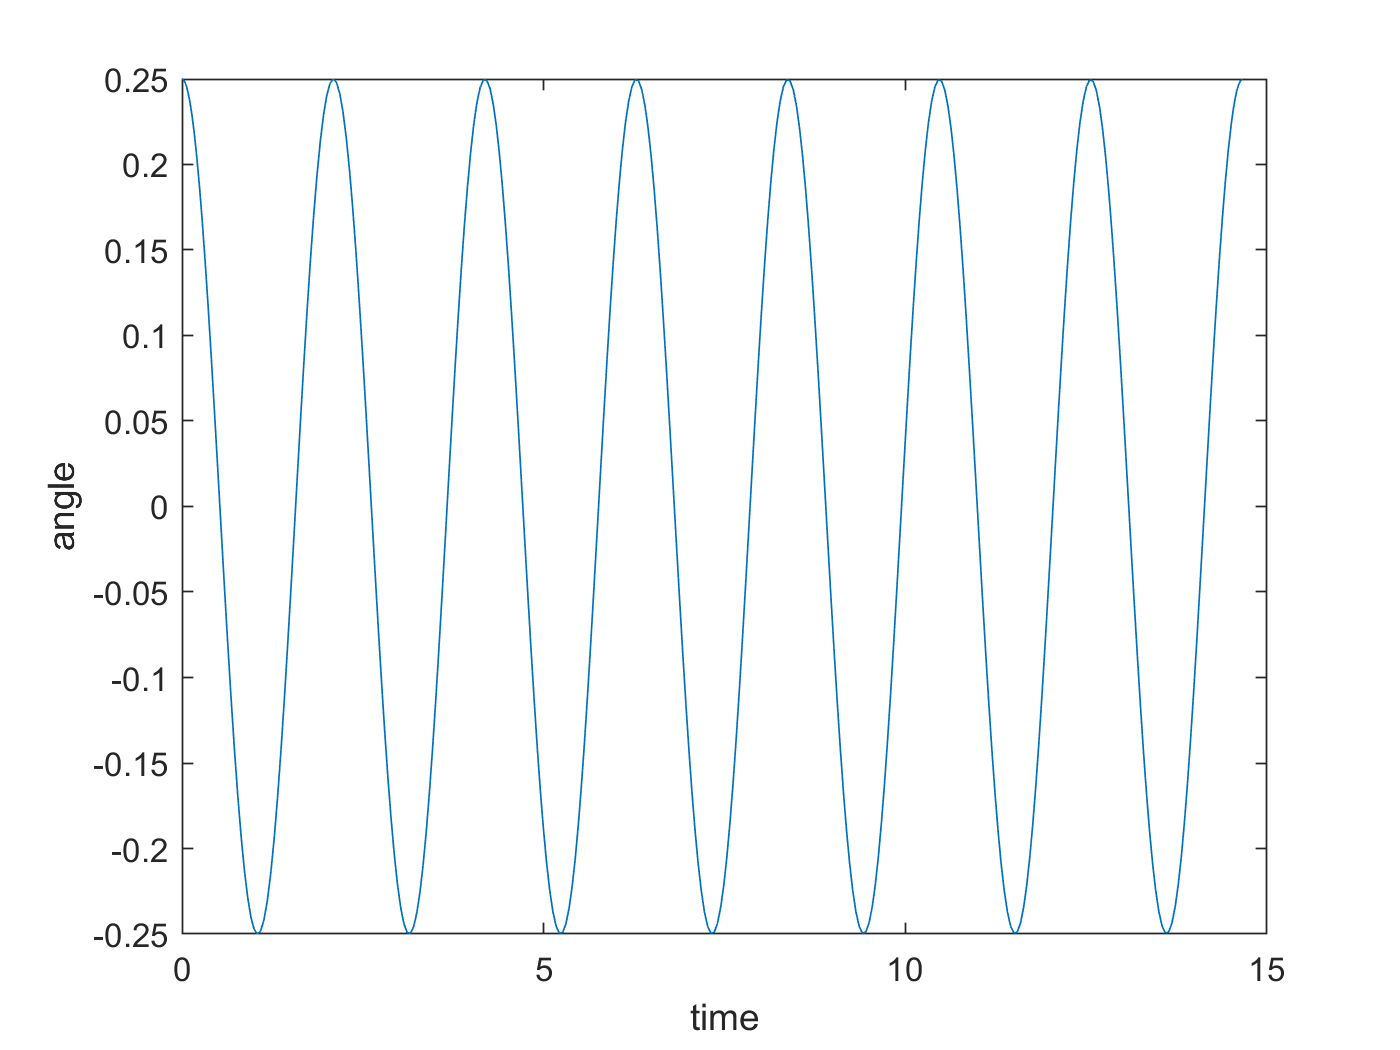

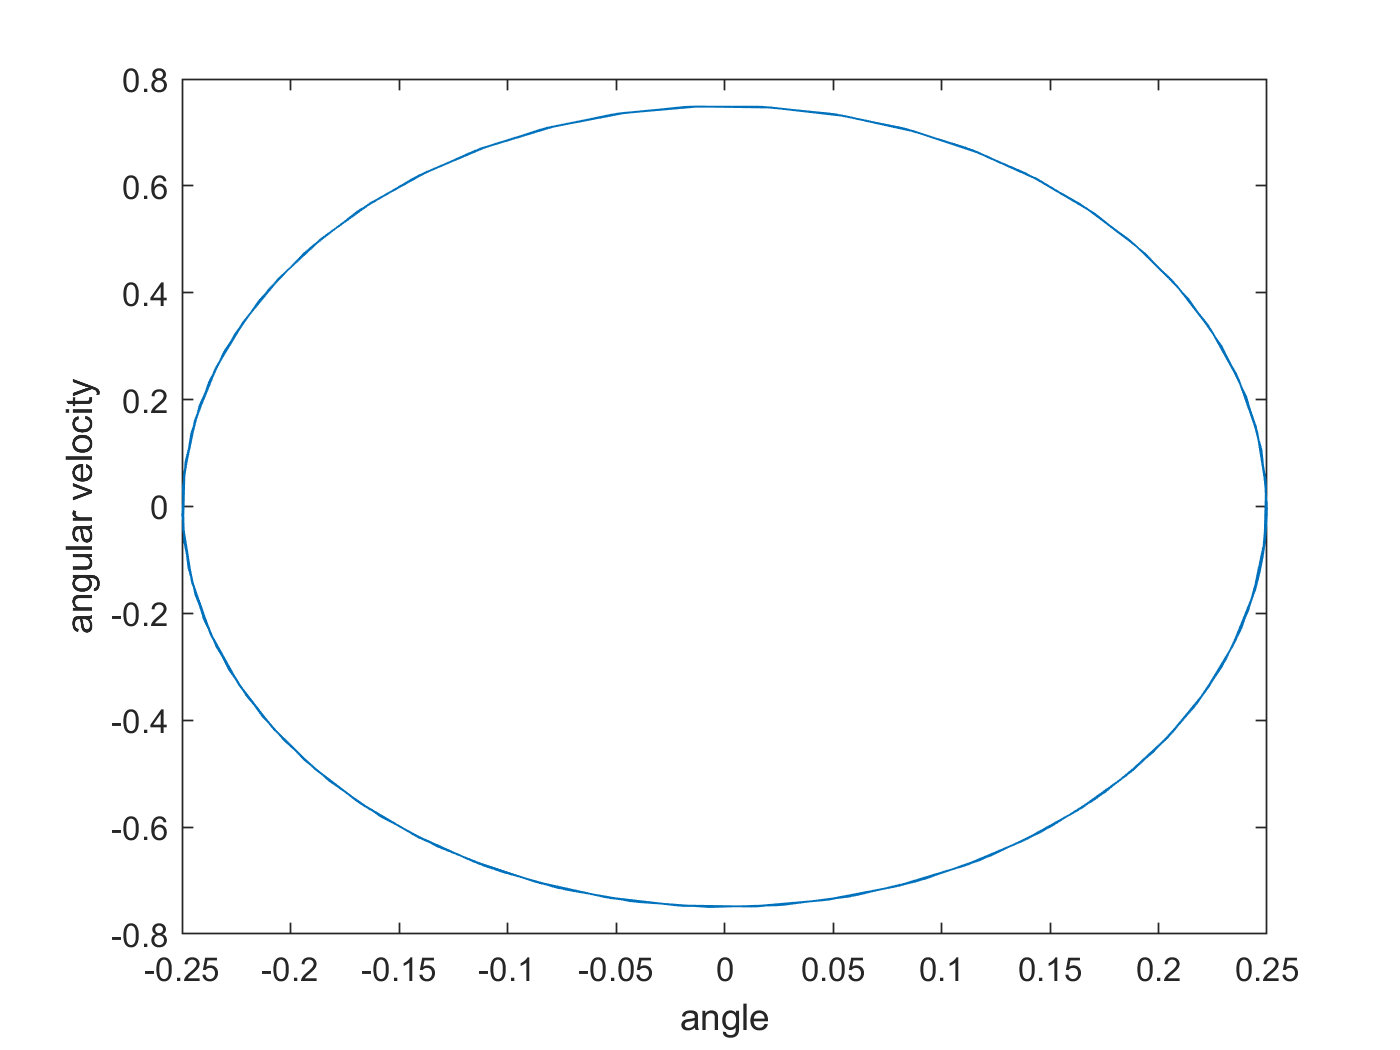

[t,w]=pendulum2(1,omega0,theta0,thetadot0);

The phase diagram in this instance will always be an ellipse whose semi-major and semi-minor axis are determined by the intial conditions of the problem. Considering the motion of the pendulum, the phase diagram should always be drawn in a CCW fashion. When the angle $\theta$ is initial positive, the angular velocity $\dot\theta_0$ is initial negative. the angular velocity only comes positive after the pendulum has swung to the other extreme.

From the solution from *pendulum2.m* we can calculate the kinetic, potential, and total energy, as well as the change in energy through one cycle by noting that 


$$E = \frac{1}{2}mL^2\dot{\theta^2}+mgL(1-\cos{\theta}) = \frac{g^2}{2\omega_0^4}\dot{\theta^2} + \frac{g^2}{2\omega_0^2}(\theta^2)
$$


taking *m=1*.

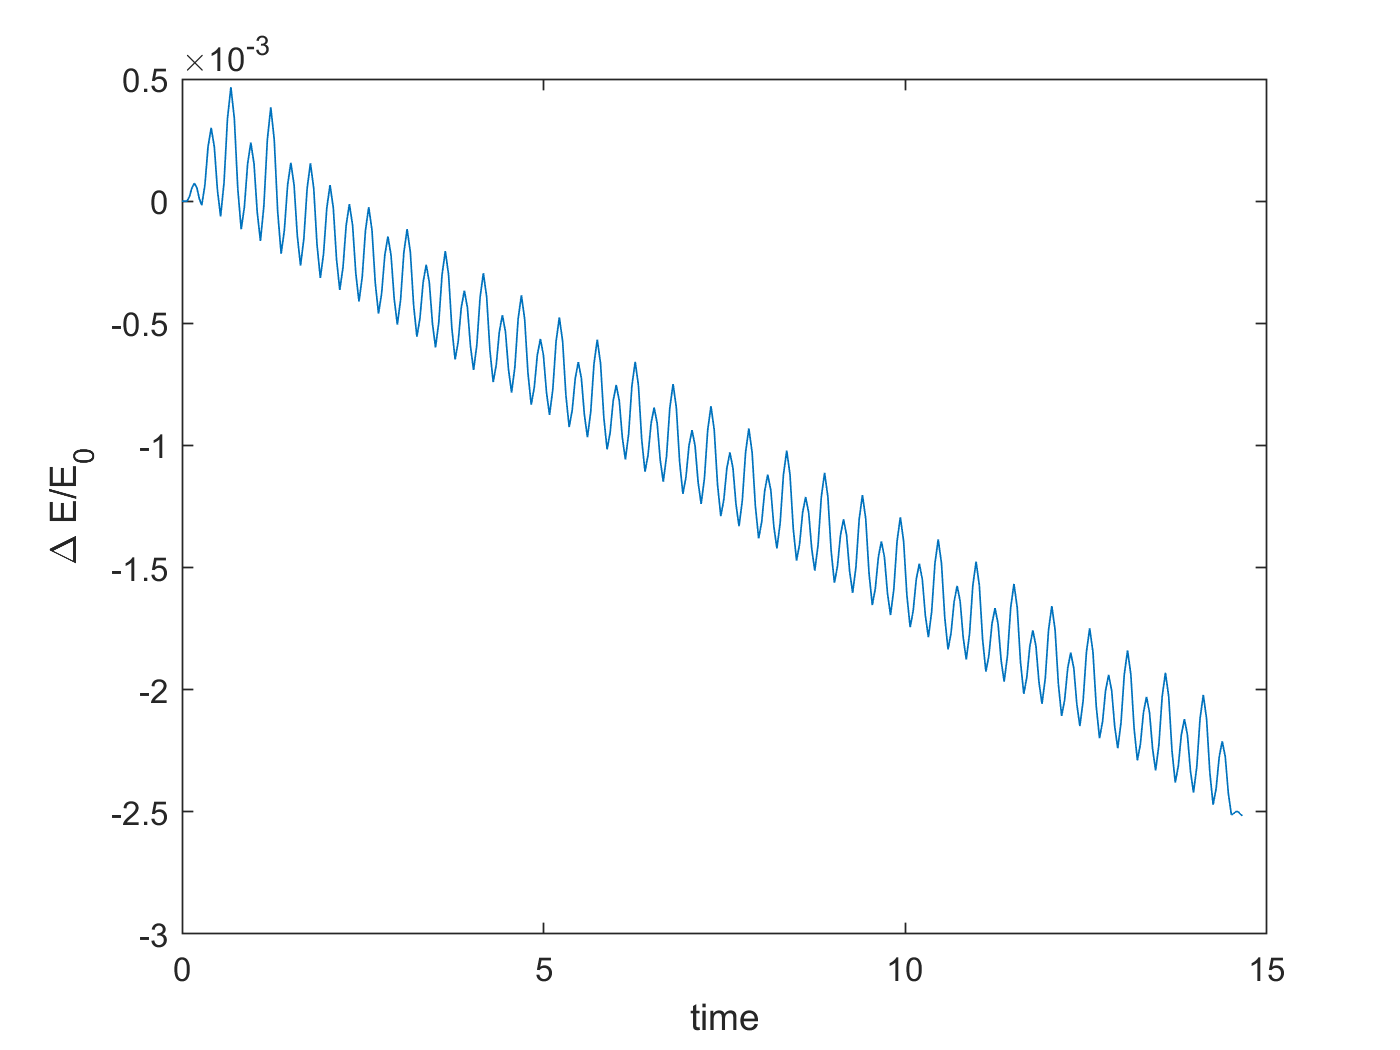

g=9.81;
[Tsmall,ind] = cyclefinder(t,w);
E0 = 0.5*g^2*(thetadot0^2)./omega0^4 + 0.5*g^2*(theta0^2)./omega0^2;
KEn =  0.5*g^2*(w(:,2).^2)./omega0^4;
PEn = 0.5*g^2*(w(:,1).^2)./omega0^2;
Delta = (KEn+PEn-E0)/E0;
plot(t,Delta)
xlabel('time')
ylabel('\Delta E/E_0')

So, the energy is conserved approximately 1 part in 10,000 every cycle. You can hardly notice it when graphing the energies

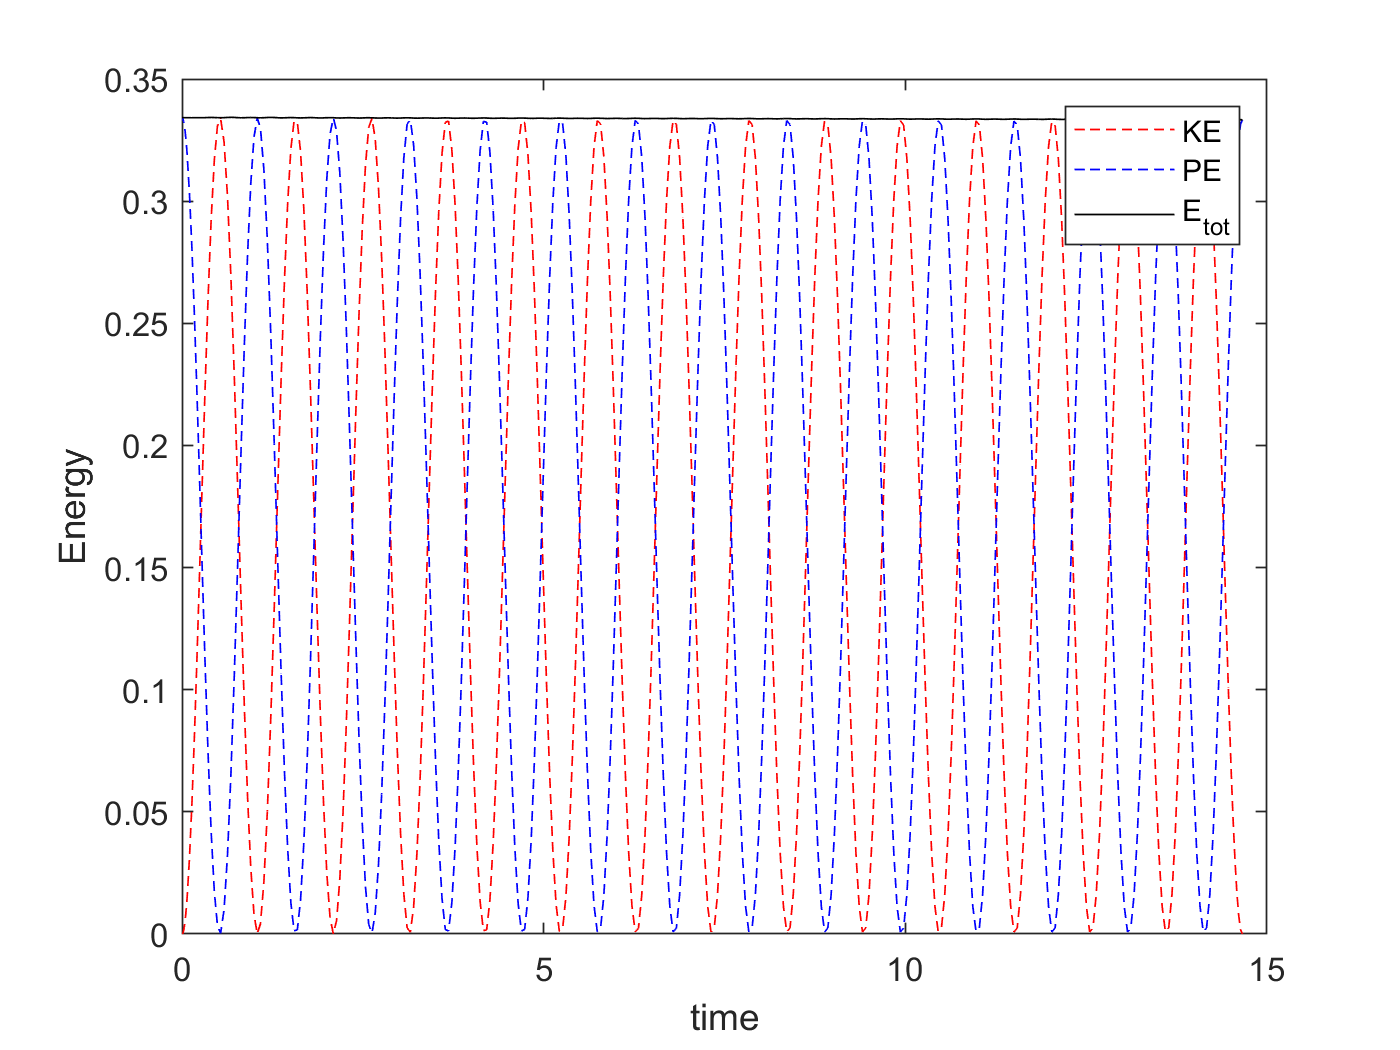

plot(t,KEn,'r--',t,PEn,'b--',t,KEn+PEn,'k')
xlabel('time')
ylabel('Energy')
legend('KE','PE',['E_{tot}'])

## **Problem 2: Large Oscillations**

## **Problem 3: Damped Oscillations**

## Problem 4: Driven Oscillations

## Problem 5: Resonances